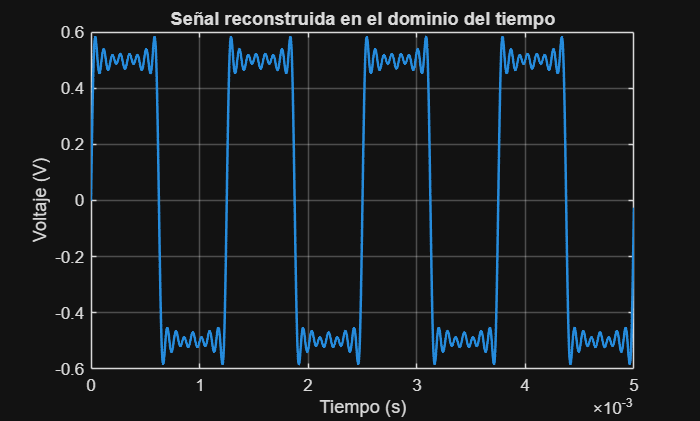

clc;
clear;
close all;

% Tiempo (5 ms)
t = 0:1e-6:(5e-3-1e-6);

% Señal reconstruida
v = 0.635352873*sin(2*pi*800*t) ...
  + 0.211599676*sin(2*pi*2400*t) ...
  + 0.127501413*sin(2*pi*4000*t) ...
  + 0.092366609*sin(2*pi*5600*t) ...
  + 0.062447492*sin(2*pi*7200*t) ...
  + 0.05827939*sin(2*pi*8800*t) ...
  + 0.048474685*sin(2*pi*10400*t) ...
  + 0.042219686*sin(2*pi*12000*t);

% Dominio del tiempo
figure;
plot(t,v,'LineWidth',1.5);
grid on;
xlabel('Tiempo (s)');
ylabel('Voltaje (V)');
title('Señal reconstruida en el dominio del tiempo');

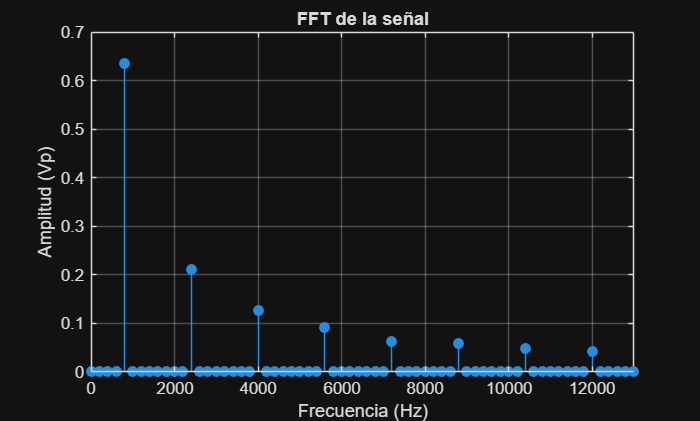


% Dominio de la frecuencia
Fs = 1/(t(2)-t(1));
N = length(v);

V = fft(v-mean(v));
P2 = abs(V)/N;
P1 = P2(1:N/2+1);
P1(2:end-1) = 2*P1(2:end-1);

f = Fs*(0:N/2)/N;

figure;
stem(f,P1,'filled');
grid on;
xlabel('Frecuencia (Hz)');
ylabel('Amplitud (Vp)');
title('FFT de la señal');
xlim([0 13000]); 